clear all, close all, clc;

% Import data from text file
% Script for importing data from the following text file:
%
%    filename: observerComparism2.csv
%
% Auto-generated by MATLAB on 13-Apr-2023 18:01:37

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 5, "Encoding", "UTF-8");

% Specify range and delimiter
opts.DataLines = [1600, 8500];
opts.Delimiter = ";";

% Specify column names and types
opts.VariableNames = ["t", "xObs", "xRef", "xCam", "xKalman"];
opts.VariableTypes = ["double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable("observerComparism2.csv", opts);

% Convert to output type
t = tbl.t / 1000;
xObs = tbl.xObs;
xRef = tbl.xRef;
xCam = tbl.xCam;
xKalman = tbl.xKalman;

% Clear temporary variables
clear opts tbl

% Preprocessing Cam
oldCam = 0;
for i = 1:length(xCam)
    if xCam(i) == 0 
        xCam(i) = oldCam;
    else
        oldCam = xCam(i);
    end
end

% Curve Fits
fncSin = @(x, b) (b(1)*sin(2*pi*b(2)*x + b(3)) + b(4))

fncSin = function_handle with value:
    @(x,b)(b(1)*sin(2*pi*b(2)*x+b(3))+b(4))


b0 = [1000, 0.1, 0, 3000];

% Fit Cam
fitCam = @(b)(sum((fncSin(t',b)-xCam').^2))

fitCam = function_handle with value:
    @(b)(sum((fncSin(t',b)-xCam').^2))


b = fminsearch(fitCam, b0)

b = 	1.0e+03 *

    0.8064    0.0001   -0.0012    2.9973


freqCam = b(2);
phaseCam = b(3);
camFit = fncSin(t, b)

camFit = 	1.0e+03 *

    3.5950
    3.5956
    3.5963
    3.5970
    3.5977
    3.5984
    3.5990
    3.5997
    3.6004
    3.6011


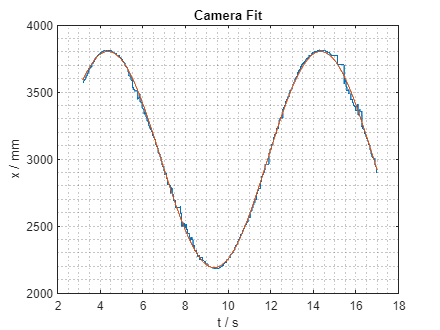

plot(t, xCam)
title("Camera Fit")
xlabel("t / s"), ylabel("x / mm")
grid minor;
hold on
plot(t, camFit)
hold off

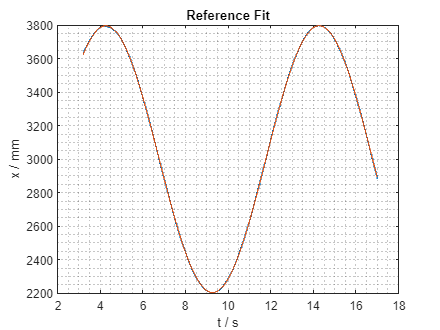


% Fit Ref
fitRef = @(b)(sum((fncSin(t',b)-xRef').^2));
b = fminsearch(fitRef, b0);
refFit = fncSin(t, b);
plot(t, xRef)
title("Reference Fit")
xlabel("t / s"), ylabel("x / mm")
grid minor;
hold on
plot(t, refFit)
hold off

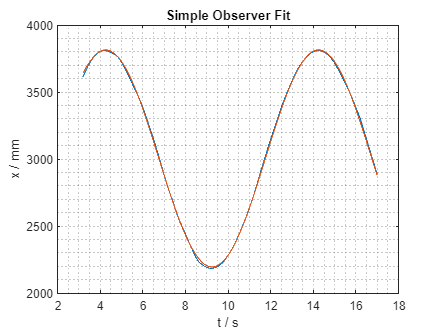



% Simple Observer Fit
fitObs = @(b)(sum((fncSin(t',b)-xObs').^2));
b = fminsearch(fitObs, b0);
freqObs = b(2);
phaseObs = b(3);
obsFit = fncSin(t, b);
plot(t, xObs)
title("Simple Observer Fit")
xlabel("t / s"), ylabel("x / mm")
grid minor;
hold on
plot(t, obsFit)
hold off


% Kalman Observer Fit
fitKalman = @(b)(sum((fncSin(t',b)-xKalman').^2))

fitKalman = function_handle with value:
    @(b)(sum((fncSin(t',b)-xKalman').^2))


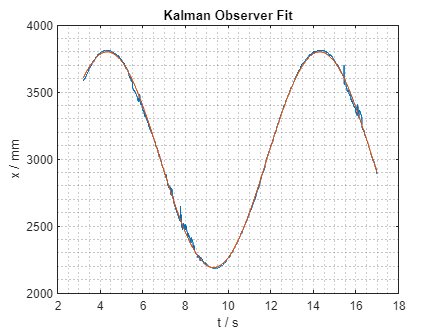

b = fminsearch(fitKalman, b0);
freqKalman = b(2);
phaseKalman = b(3);
kalmanFit = fncSin(t, b);
plot(t, xKalman)
title("Kalman Observer Fit")
xlabel("t / s"), ylabel("x / mm")
grid minor;
hold on
plot(t, kalmanFit)
hold off

## Comparism of Observers

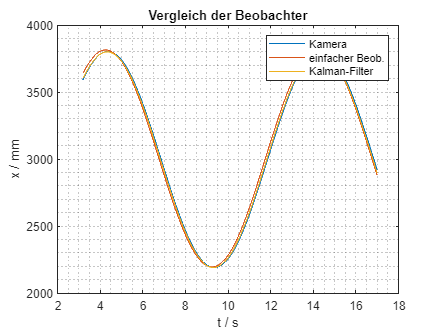

plot(t, camFit)
title("Vergleich der Beobachter")
xlabel("t / s"), ylabel("x / mm")
grid minor
hold on
plot(t, obsFit)
plot(t, kalmanFit)
hold off
legend("Kamera", "einfacher Beob.", "Kalman-Filter")


phaseDelayObs = (phaseObs - phaseCam) / (2*pi) / freqCam

phaseDelayObs = 0.1145

phaseDelayKalman = (phaseKalman - phaseCam) / (2*pi) / freqCam

phaseDelayKalman = 0.0288